# Introduction to Kriging (Gaussian Process)

## 				Prof. Joseph MORLIER

Figure 1 illustrates a typical example of a prediction problem: given some noisy observations of a dependent variable at certain values of the independent variable , what is our best estimate of the dependent variable at a new value x* ? 

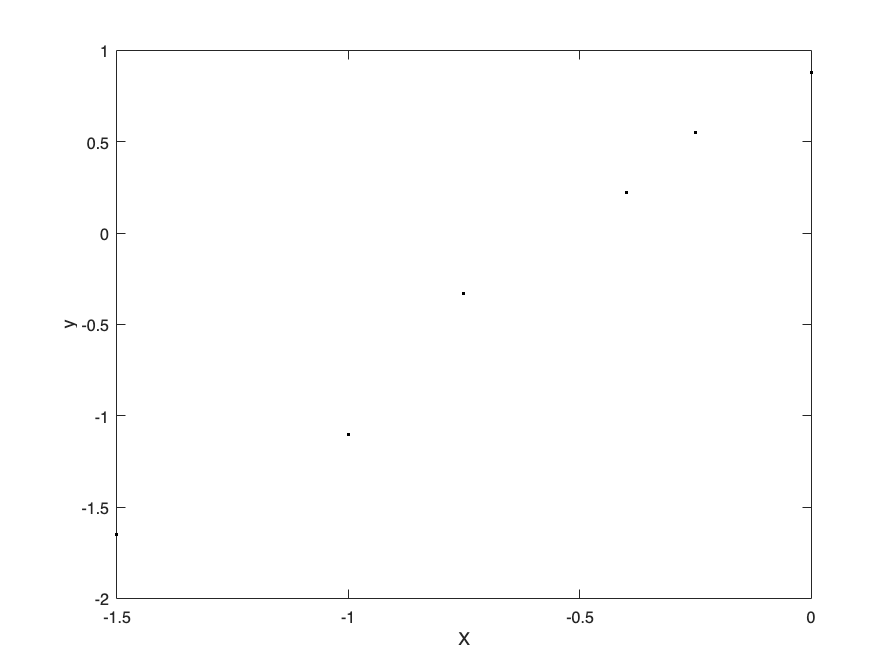

%clear all; close all;
%printoptions;


%  Inputs
X = [-1.5 -1 -.75 -.4 -.25 0]'; n = size(X,1);
% Outputs
y = .55*[-3 -2 -.6 .4 1 1.6]'; 
%
figure;
plot(X,y,'k.')
xlabel('X'); ylabel('y');

What if we want to estimate the model at a new point  x* defined as 18 points in [-1.5,0]. Please check also x*= 0.2 (extrapolation) !!

The regression problem is defined as follows:

Let $$\mathbf{x}_i \in {R}^{6}$ $ be an input vector and $$\mathbf{y}_i \in {R}^{6}$$ be its corresponding target. The set of $$M$$ inputs are arranged into a matrix $$\mathbf{X} = [\mathbf{x}_1, \dots, \mathbf{x}_M]^\top$$ and their corresponding targets are stored in a matrix $$\mathbf{Y} = [\mathbf{y}_1 - \mathbf{\bar{y}}, \dots, \mathbf{y}_M-\mathbf{\bar{y}}]^\top$, with $\mathbf{\bar{y}}$ $being the mean target value in $$\mathbf{Y}$$.

%xstar= 0.2; %extrapolation
xstar=-1.5:0.1: 0.2; %18 points in [-1.5,0] interpolation
N = length(xstar);
%computing covariance in matrix form
[covXXInd1 covXXInd2] = meshgrid(X,X)

covXXInd1 =    -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0


covXXInd2 =    -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500   -0.7500
   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000
   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500
         0         0         0         0         0         0



%computing Kstar
[covXXsInd1 covXXsInd2] = meshgrid(X,xstar)

covXXsInd1 =    -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0
   -1.5000   -1.0000   -0.7500   -0.4000   -0.2500         0


covXXsInd2 =    -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000
   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000
   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000
   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000
   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.9000   -0.9000   -0.9000   -0.9000   -0.9000   -0.9000
   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000
   -0.7000   -0.7000   -0.7000   -0.7000   -0.7000   -0.7000
   -0.6000   -0.6000   -0.6000   -0.6000   -0.6000   -0.6000


%computing Kstarstar
[covXsXsInd1 covXsXsInd2] = meshgrid(xstar,xstar)

covXsXsInd1 =    -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000
   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000
   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000
   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000
   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000
   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000 

covXsXsInd2 =    -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000   -1.4000
   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000
   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000
   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000   -1.1000
   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000 

hey hey add something missing, we may need parameters to fit "a model" of our covariance matrix. Let's try with a Standard Exponential (SE) Kernel.


$$k(x,x') =\sigma_f^2\exp\left(-\frac{(x-x')^2}{l^ 2}\right)$$


l = 1; % first hyperparameter
sig_f = 3^(1/4); % second

covXsXs = sig_f^2 * exp(-(covXsXsInd1-covXsXsInd2).^2 ./ l.^2)

covXsXs =     1.7321    1.7148    1.6641    1.5830    1.4760    1.3489    1.2084    1.0611    0.9133    0.7705    0.6372    0.5165    0.4104    0.3196    0.2440    0.1826    0.1339    0.0963
    1.7148    1.7321    1.7148    1.6641    1.5830    1.4760    1.3489    1.2084    1.0611    0.9133    0.7705    0.6372    0.5165    0.4104    0.3196    0.2440    0.1826    0.1339
    1.6641    1.7148    1.7321    1.7148    1.6641    1.5830    1.4760    1.3489    1.2084    1.0611    0.9133    0.7705    0.6372    0.5165    0.4104    0.3196    0.2440    0.1826
    1.5830    1.6641    1.7148    1.7321    1.7148    1.6641    1.5830    1.4760    1.3489    1.2084    1.0611    0.9133    0.7705    0.6372    0.5165    0.4104    0.3196    0.2440
    1.4760    1.5830    1.6641    1.7148    1.7321    1.7148    1.6641    1.5830    1.4760    1.3489    1.2084    1.0611    0.9133    0.7705    0.6372    0.5165    0.4104    0.3196
    1.3489    1.4760    1.5830    1.6641    1.7148    1.7321    1.7148    1.6641    1

covXX = sig_f^2 * exp(-(covXXInd1-covXXInd2).^2 ./ l.^2)

covXX =     1.7321    1.3489    0.9869    0.5165    0.3631    0.1826
    1.3489    1.7321    1.6271    1.2084    0.9869    0.6372
    0.9869    1.6271    1.7321    1.5324    1.3489    0.9869
    0.5165    1.2084    1.5324    1.7321    1.6935    1.4760
    0.3631    0.9869    1.3489    1.6935    1.7321    1.6271
    0.1826    0.6372    0.9869    1.4760    1.6271    1.7321



covXXs = sig_f^2 * exp(-(covXXsInd1-covXXsInd2).^2 ./ l.^2)

covXXs =     1.7321    1.3489    0.9869    0.5165    0.3631    0.1826
    1.7148    1.4760    1.1352    0.6372    0.4615    0.2440
    1.6641    1.5830    1.2799    0.7705    0.5751    0.3196
    1.5830    1.6641    1.4145    0.9133    0.7024    0.4104
    1.4760    1.7148    1.5324    1.0611    0.8410    0.5165
    1.3489    1.7321    1.6271    1.2084    0.9869    0.6372
    1.2084    1.7148    1.6935    1.3489    1.1352    0.7705
    1.0611    1.6641    1.7277    1.4760    1.2799    0.9133
    0.9133    1.5830    1.7277    1.5830    1.4145    1.0611
    0.7705    1.4760    1.6935    1.6641    1.5324    1.2084


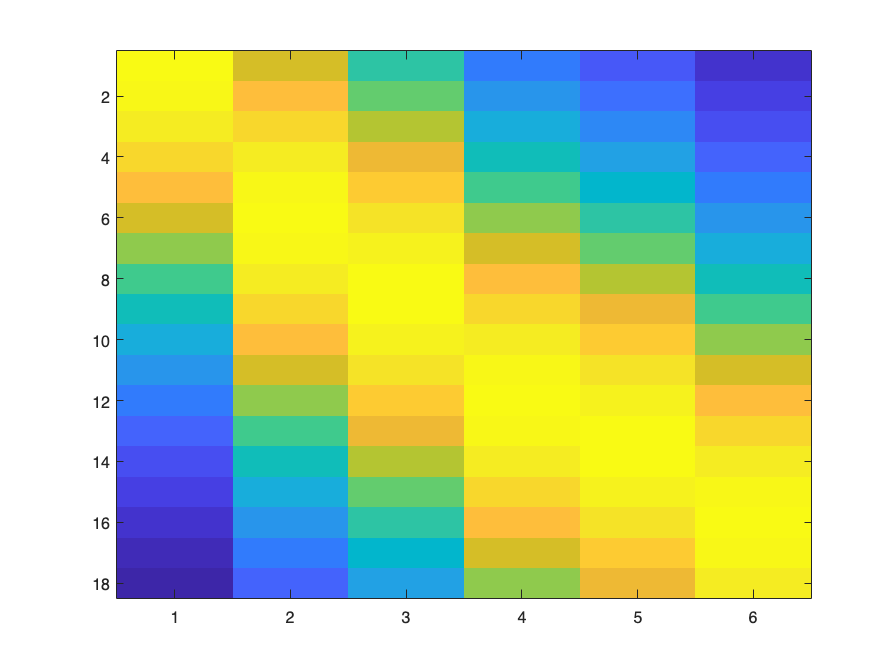

figure;
imagesc(covXXs); % Plotting the Gram Matrix

I wish to train a GPR model $$\mathcal{G} = \lbrace \mathbf{X}, \mathbf{Y}, \theta \rbrace$$ using the squared exponential function ($$\theta$$ must be chosen):

$$k(\mathbf{x}_i, \mathbf{x}_j) = \sigma_f^2 \text{exp} \left( - \frac{1}{l^2}(\mathbf{x}_i - \mathbf{x}_j)^2\right) + \sigma_n^2\delta_{ij}$$, where $$\delta_{ij}$$ equals $$1$$ if $$i = j$$ and $$0$$ otherwise. 

sig_n=0.3

sig_n = 0.3000

 %sig_n=0 %instead

covXX_noisy = covXX + sig_n^2 *eye(size(covXX))

covXX_noisy =     1.8221    1.3489    0.9869    0.5165    0.3631    0.1826
    1.3489    1.8221    1.6271    1.2084    0.9869    0.6372
    0.9869    1.6271    1.8221    1.5324    1.3489    0.9869
    0.5165    1.2084    1.5324    1.8221    1.6935    1.4760
    0.3631    0.9869    1.3489    1.6935    1.8221    1.6271
    0.1826    0.6372    0.9869    1.4760    1.6271    1.8221


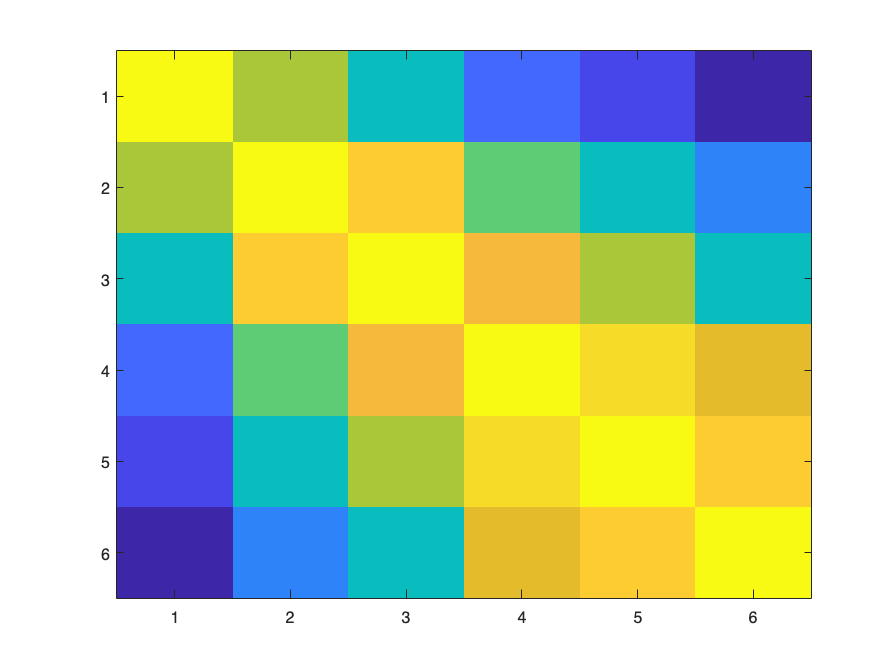

figure;
imagesc(covXX_noisy); % Plotting the Gram Matrix


posterior_mean = covXXs/covXX_noisy * y 

posterior_mean =    -1.5845
   -1.5472
   -1.4677
   -1.3478
   -1.1914
   -1.0046
   -0.7948
   -0.5706
   -0.3409
   -0.1145


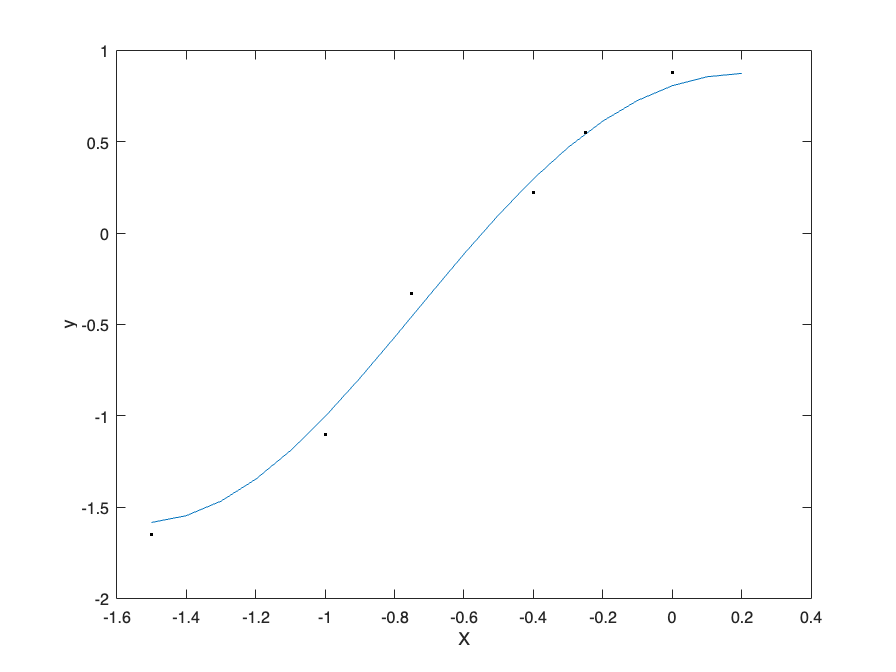

figure;plot(xstar,posterior_mean); hold on;
plot(X,y,'k.'); xlabel('X'); ylabel('y');

Compute the 95% confidence interval

posterior_cov = covXsXs - covXXs/covXX_noisy * covXXs'

posterior_cov =     0.0776    0.0652    0.0517    0.0383    0.0257    0.0147    0.0058   -0.0005   -0.0045   -0.0061   -0.0060   -0.0047   -0.0027   -0.0005    0.0014    0.0028    0.0035    0.0035
    0.0652    0.0621    0.0561    0.0476    0.0376    0.0269    0.0166    0.0076    0.0005   -0.0042   -0.0066   -0.0069   -0.0054   -0.0028    0.0003    0.0034    0.0060    0.0078
    0.0517    0.0561    0.0564    0.0529    0.0461    0.0369    0.0265    0.0161    0.0068   -0.0004   -0.0052   -0.0073   -0.0070   -0.0047   -0.0012    0.0029    0.0069    0.0103
    0.0383    0.0476    0.0529    0.0538    0.0506    0.0438    0.0346    0.0242    0.0140    0.0051   -0.0016   -0.0057   -0.0070   -0.0058   -0.0028    0.0014    0.0061    0.0105
    0.0257    0.0376    0.0461    0.0506    0.0508    0.0470    0.0401    0.0311    0.0213    0.0118    0.0038   -0.0020   -0.0052   -0.0058   -0.0042   -0.0009    0.0034    0.0080
    0.0147    0.0269    0.0369    0.0438    0.0470    0.0466    0.0428    0.036

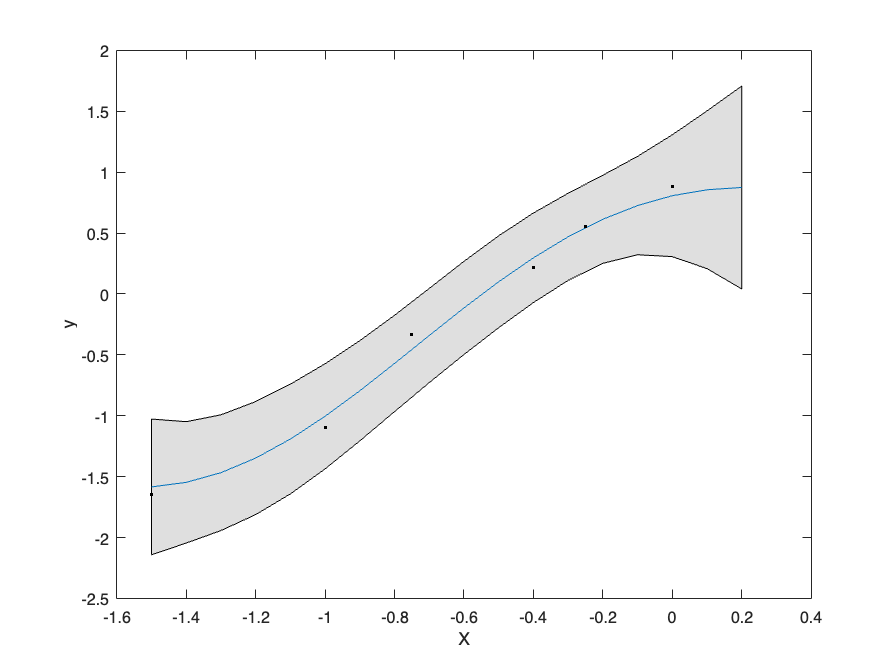

% Plotting mean, variance and sample of the posterior % Plotting the variance of Prior
f = [posterior_mean+2*sqrt(diag(posterior_cov));flipdim(posterior_mean -2*sqrt(diag(posterior_cov)),1) ];
%%bounds = [posterior_mean+1.96*sqrt(posterior_cov) posterior_mean-1.96*sqrt(posterior_cov)]

xf=[xstar'; flipdim(xstar',1)];
figure; fill(xf, f, [7 7 7]/8);hold on; plot(xstar,posterior_mean); hold on;
plot(X,y,'k.'); xlabel('X'); ylabel('y');

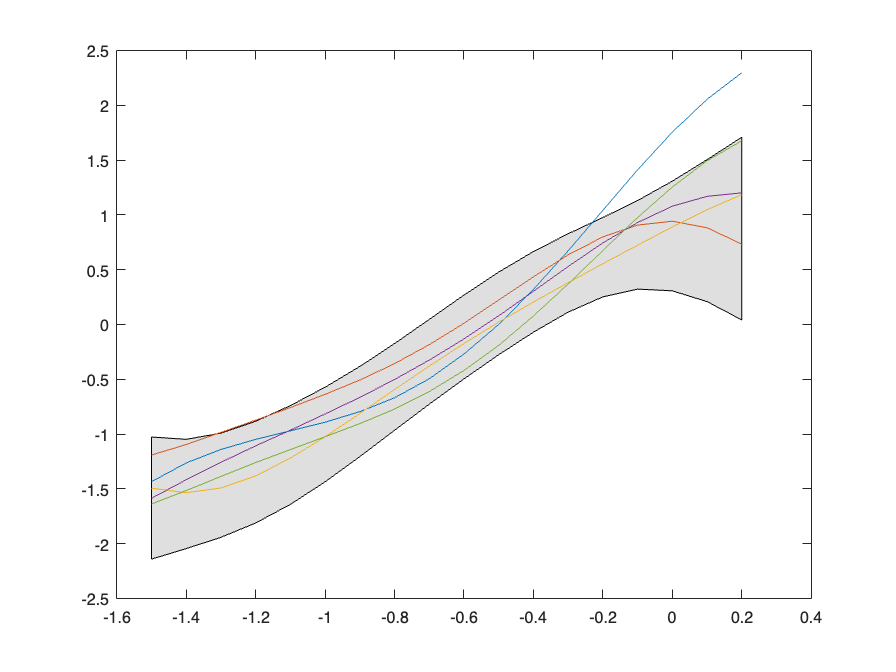

% Tip: add a jitter term to the gram matrix so that matrix inversion is numerically stable
jitter = 10^(-6);
% The cholesky decomposition
L = chol(posterior_cov + eye(N)*jitter);
% Plotting the randomly drawn sample function
randomFunction = posterior_mean + L'*randn(N,5); 
figure; fill(xf, f, [7 7 7]/8);hold on; plot(xstar , randomFunction);

 but is there a way to find the $\theta_{optimal}$ ? oh $\theta = [l, \sigma_f, \sigma_n]$

The hyperparameters are $\theta = [l, \sigma_f, \sigma_n]$ with $$\sigma_n$$ being the assumed noise level in the training data and $$l$ $ is the length-scale  (of oscillations) and $$\sigma_f$$ the amplitude.

To train the model, I need to minimise the negative log marginal likelihood with respect to the hyperparameters:


$$$-\text{log}\, p(\mathbf{Y} \mid \mathbf{X}, \theta) = \frac{1}{2} \text{tr}(\mathbf{Y}^\top\mathbf{K}^{-1}\mathbf{Y}) + \frac{1}{2}\text{log}\mid\mathbf{K}\mid + \,c,$$$


where c is a constant and the matrix $$\mathbf{K}$ $is a function of the hyperparameters (see equation k(xi,xj) = ...).

Based on the demo given on the GPML website, Let's try to implement this using the GPML Matlab code is below.